# **demo18 of Im2mesh package**

demo18 - Create tetrahedral mesh based on 2d image

Cite as: Ma, J., & Li, Y. (2025). Im2mesh: A MATLAB/Octave package for generating finite element mesh based on 2D multi-phase image (2.1.5). Zenodo. [https://doi.org/10.5281/zenodo.14847059](https://doi.org/10.5281/zenodo.14847059)

Jiexian Ma, mjx0799@gmail.com. [Project website](https://github.com/mjx888/im2mesh).

## Note

I suggest familiarizing yourself with Im2mesh_GUI before learning Im2mesh package. With graphical user interface, Im2mesh_GUI will help you better understand the workflow and parameters of Im2mesh package.

Im2mesh_GUI: [https://www.mathworks.com/matlabcentral/fileexchange/179684-im2mesh_gui-2d-image-to-finite-element-mesh](https://www.mathworks.com/matlabcentral/fileexchange/179684-im2mesh_gui-2d-image-to-finite-element-mesh)

If you are using Im2mesh package in MATLAB,  you need to install MATLAB Image Processing Toolbox and Mapping Toolbox because Im2mesh package use a few functions in these toolboxes.

**To run demo18, you need to have MATLAB Partial Differential Equation Toolbox.**

## Setup

Before we start, please set folder "Im2mesh_Matlab" as your current folder of MATLAB.

clearvars

Set default image size.

x = 250; y = 250; width = 400; height = 400;
set(groot, 'DefaultFigurePosition', [x,y,width,height])
% To reset:
% set(groot, 'DefaultFigurePosition', 'factory')

We add the folder 'mesh2d-master' to the path of MATLAB. 

addpath(genpath('mesh2d-master'))

## Import image

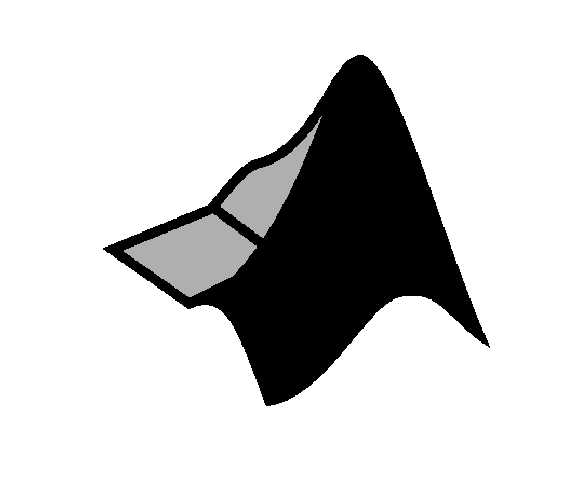

im = imread('logo.tif');
if size(im,3) == 3;  im = rgb2gray( im ); end
imshow( im,'InitialMagnification','fit' );

## Get boundries from image

We have demostrate how to do this in example3 of demo01.mlx

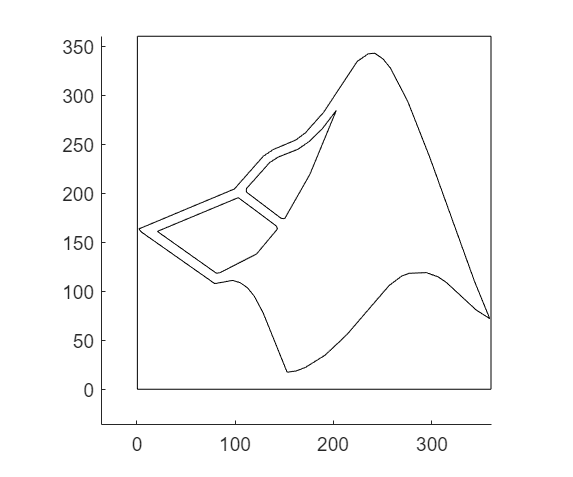

opt = [];   % reset opt
opt.tolerance = 1;
opt.tf_mesh = false;

bounds = im2mesh( im, opt );

% bounds is the simplified polygonal boundaries
plotBounds( bounds );

## Generate 2d mesh

hmax = 500; 
grad_limit = 1;
opt = [];
opt.disp = inf;     % silence verbosity

[vert,tria,tnum,vert2,tria2] = bounds2mesh( bounds, hmax, grad_limit, opt );

Plot mesh.

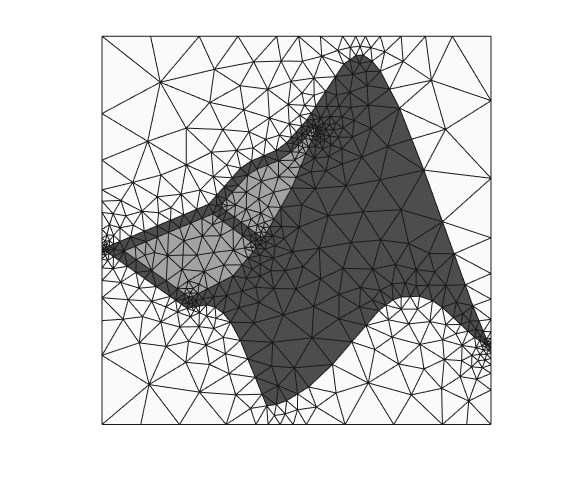

plotMeshes(vert,tria,tnum);

## Create 2d PDE model 

We can use the following command to create 2d PDE model object (for Matlab PDE toolbox).

% Create matlab pde model object
model2d = createpde();  % qudratic model

geometryFromMesh( model2d, vert2', tria2', tnum' );

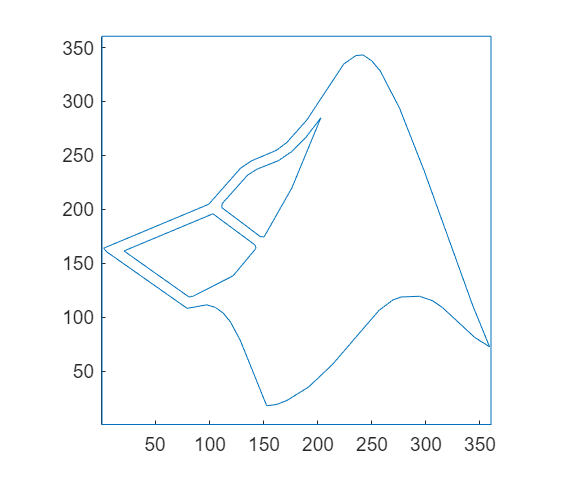

g = model2d.Geometry;
pdegplot( g, "FaceLabels", "on" )

## Extrude 2d geometry

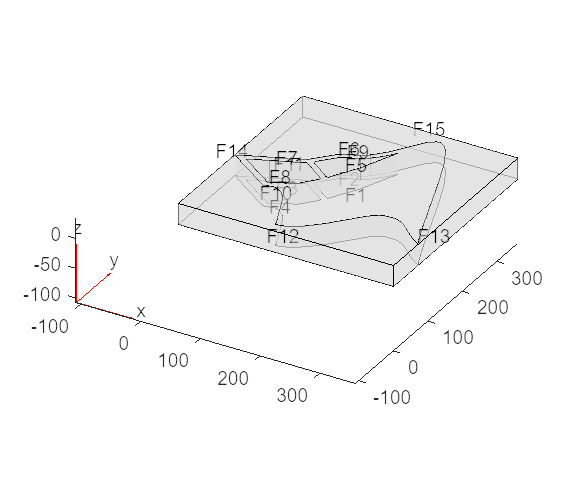

height = 35;
extrude( g, height );

pdegplot( g, "FaceLabels", "on", "FaceAlpha", 0.5 )

## Create 3d PDE model 

model3d = createpde;
model3d.Geometry = g;

## Generate Mesh

generateMesh( model3d, 'Hmax',500, 'Hmin', 5, 'Hgrad', 1.2 )

ans =   FEMesh with properties:

             Nodes: [3×29285 double]
          Elements: [10×18562 double]
    MaxElementSize: 500
    MinElementSize: 5
     MeshGradation: 1.2000
    GeometricOrder: 'quadratic'


## Plot mesh

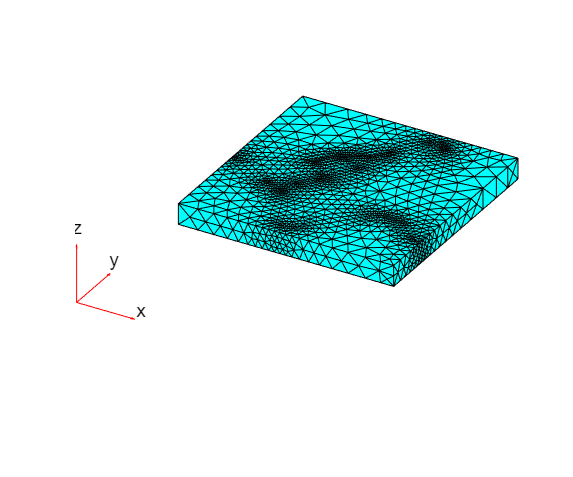

pdemesh(model3d)

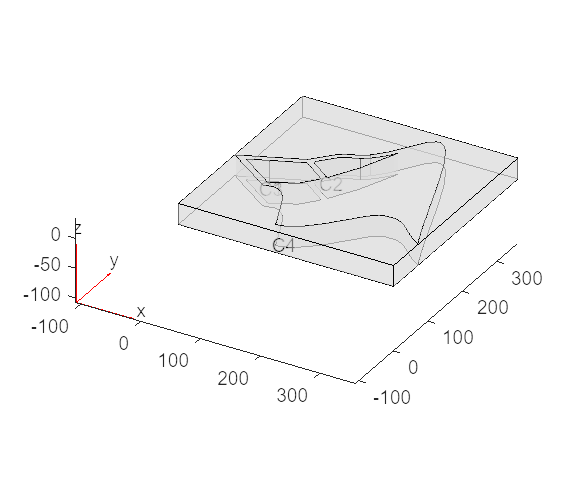

pdegplot(model3d, 'CellLabels','on', 'FaceAlpha',0.5);

## Find elements in different regions

numCell = model3d.Geometry.NumCells;
elementIDsCell = cell( [1, numCell] );

for i = 1: numCell
    elementIDsCell{i} = findElements( model3d.Mesh, "region", Cell=i );
end

## Plot mesh

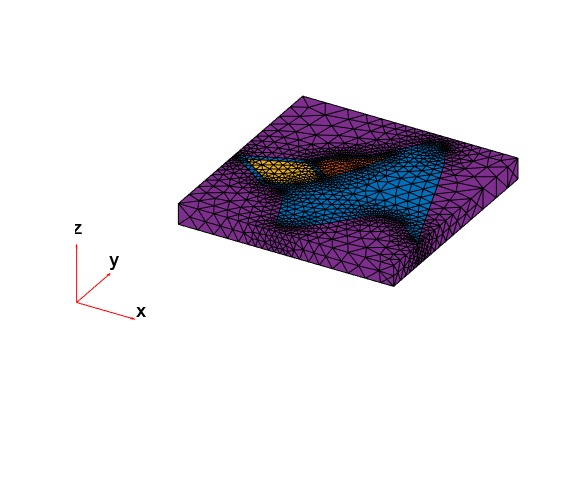

colors = lines(numCell);
figure
for i = 1: numCell
    pdemesh( model3d.Mesh.Nodes, ...
             model3d.Mesh.Elements(:,elementIDsCell{i}), ...
             'FaceColor', colors(i,:))
    hold on
end
hold off

## Change view angle

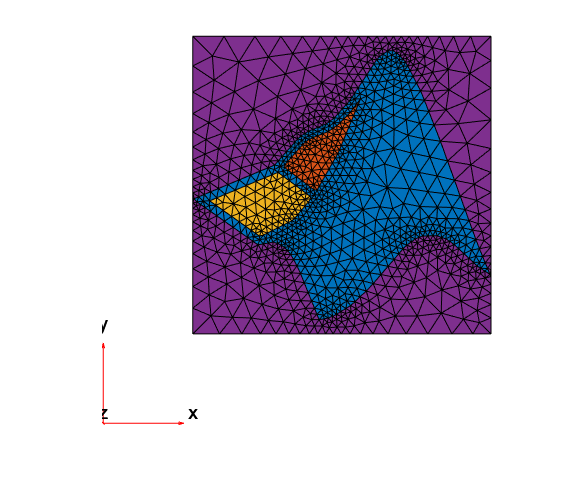

colors = lines(numCell);
figure
for i = 1: numCell
    pdemesh(model3d.Mesh.Nodes, ...
            model3d.Mesh.Elements(:,elementIDsCell{i}), ...
            'FaceColor', colors(i,:))
    hold on
end
view([-0 90])
hold off

## Note

The input image has 3 phases. However, the generated tetrahedral mesh has 4 phases. This does not meet our objective.

I may fix this issue in the next update of Im2mesh.

An alternative approach is to use Gmsh.

## Evaluate mesh quality

Q = meshQuality( model3d.Mesh );
mean(Q)

ans = 0.8555

min(Q)

ans = 0.2720

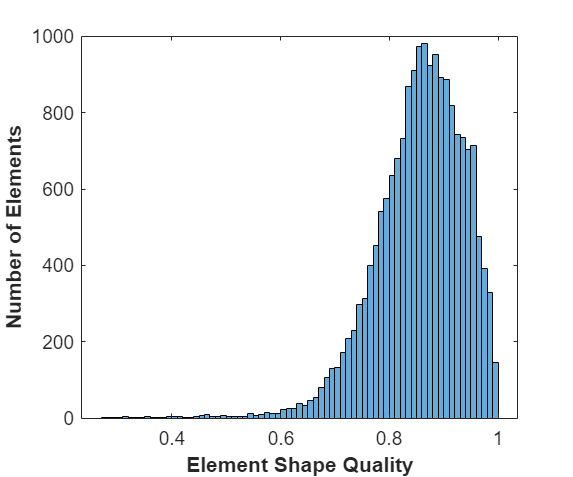

figure
histogram(Q)
xlabel( "Element Shape Quality", "fontweight", "b" )
ylabel( "Number of Elements", "fontweight", "b" )

% reset image size
set(groot, 'DefaultFigurePosition', 'factory')

% end of demo